# Low Speed Light Aircraft Drag Audit

Author: Declan Clifford

Project Supervisor: Professor Keith Towell

**THE DRAG AUDIT IS SELF CONTAINED WITHIN "aircraft_flight_dynamic_model". THIS LIVE SCRIPT IS ONLY FOR DEMONSTRATION PURPOSES.**

**THE MOST UP TO DATE VERSION OF THE DRAG AUDIT IS CONTAINED WITHIN "aircraft_flight_dynamic_model" AND SO THIS LIVE SCRIPT MAY CONTAIN ERRORS OR OUTDATED INFORMATION.**

This script follows the drag component build up method outlined by S.Gudmundsson under Section 15.4.6: "The Component Drag Build-Up Method" in "General Aviation Aircraft Design". The method has been simplified to the sections only considering the drag of a low speed light aircraft of simple geometry (i.e. unswept wings).

Many of the methods and procedures Gudmundsson describes are taken from Hoerner's "Fluid Dynamic Drag".

This method considers the drag of the entire aircraft as split into three distinct groups

- Parasite Drag

- Vortex Induced Drag

- Miscellaneous Drag

## Flight Conditions

% flight conditions
nu=1.460e-5;                  % kinematic viscosity        (m^2/s)
mu=1.789e-5;                  % dynamic viscosity          (Pa/s)
rho=1.225;                    % free stream density        (kg/m^3)
V=43.21;                      % flight speed               (m/s)
g=9.81;                       % gravitational acceleration (m/s^2)

## Aircraft Specifcations

% aircraft specs
m=499;                        % aircraft mass              (kg)
n=1;                          % load factor                [-]

Cm0=-0.087;                   % zero lift pitching...
                              % moment coefficient         [-]

% main wing (NACA 4409)
b_w=8.7;                      % wing span                  (m)
c_w=1.17;                     % wing reference chord       (m)
s_w=b_w*c_w;                  % wing reference area        (m)
AR_w=(b_w^2)/s_w;             % wing aspect ratio          [-]

h0=0.250;                     % dist from wing le to ac...
                              % as a percentage of wing chord [-]
                              
h=0.364;                      % dist from wing le to cg...
                              % as a percentage of wing chord [-]
                              
% horizontal tail plane (flate plate)
b_tp=2.44;                    % horizontal tail plane span            (m)
c_tp=0.880;                   % horizontal tail plane reference chord (m)
s_tp=2.0618;                  % tail plane reference area             (m^2)
AR_tp=(b_tp^2)/s_tp;          % tail plane aspect ratio               [-]


l_ac=3.48;                    % dist from wing AC to tailplane AC (m)
l_t=l_ac-(c_w*(h-h0));        % dist from tail ac to cg           (m)
lw=(h-h0)*c_w;                % dist from wing ac to cg           (m)

K=s_tp*l_t/(s_w*c_w);        % tail volume fraction              [-]

% vertical tail plane (flate plate)
c_tp_v=0.715;                 % vertical tail chord (m)
b_tp_v=2.2;                   % vertical tail span (m)
s_tp_v=c_tp_v*b_tp_v;         % vertical tail reference area (m^2)

% approx fuselage geometry
c_f=5.49;                     % fuselage length 
b_f_h=1;                      % fuselage max height
b_f_w=1;                      % fuselage max width
A_f=b_f_h*b_f_w;              % fuselage max area
s_f_wet=15.0;                 % approx fuselage wetted area

## Aircraft Lift Coefficients in Steady Level Flight

CLtot=n*m*g/(0.5*rho*(V^2)*s_w);                    % total aircraft lift coefficient [-]
CL_tp=(Cm0+CLtot*(h-h0))/(((s_tp/s_w)*(h-h0))+K)   % tail lift coefficient           [-]

CL_tp = -0.1633

CL_w=CLtot-CL_tp*(s_tp/s_w);                        % main wing lift coefficient      [-]

## Parasite Drag

A general method for determining the parasitic drag contribution of a body is given below.

### 1. General Parasitic Drag Calculation Method

#### 1.1 Reynolds Number

The Reynolds Number can first be found using


$$R_e =\frac{\rho \textrm{Vc}}{\nu }$$


where $\rho$ is the fluid density (kg/m^3), $\mathrm{V}$ is the fluid reference speed (m/s) and $\mathrm{c}$ is a reference length (m) (for example wing chord). Before proceeding the cutoff Reynolds Number should be determined using 


$$R_{e,\textrm{cutoff}} =38\ldotp 21{\left(\frac{c}{\kappa }\right)}^{1\ldotp 053}$$


where $\kappa$ is a skin roughness value. If $R_e$ exceeds $R_{e,\textrm{cutoff}}$ then $R_{e,\textrm{cutoff}}$ should be used.

Some typical $\kappa$ values are given in the following table recreated from Gudmundsson and converted from ft to m.

**_________________________________________**

**Surface Type                                        **$\kappa$** (c in m)**

**_________________________________________**

Camouflage paint on aluminium           $1\ldotp 01\times {10}^{-5}$

Smooth paint                                        $0\ldotp 63\times {10}^{-5}$

Production sheet metal                        $0\ldotp 41\times {10}^{-5}$

Polished sheet metal                           $0\ldotp 15\times {10}^{-5}$

Smooth molded composite                  $0\ldotp 05\times {10}^{-5}$

**_________________________________________**

#### **1.2 Skin Friction Coefficient - Fully Turbulent Flow Assumption**

Assuming fully turbulent flow the skin friction coefficient over a flat plate can be found using the Schlichting relation


$$C_{f,\textrm{turb}} \frac{0\ldotp 455}{{\left(\log_{10} \left(R_e \right)\right)}^{2\ldotp 58} }$$


#### 1.3 Skin Friction Drag Coefficient

The skin friction drag coefficient can then be determined using


$$C_{\textrm{Df}} =\frac{S_{\textrm{wet}} }{S_{\textrm{ref}} }C_{f,\textrm{turb}}$$


where $S_{\textrm{wet}}$ is the surface wetted area (m^2) and $S_{\textrm{ref}}$ is some reference area (m^2), typically the wing reference area.

#### **1.4 Form Component Factor**

The skin friction drag coefficient term found in the previous step can be multiplied with a form factor term. The component form factor is a measure of pressure drag due to viscous separation. It effectively accounts for the effect of shape geometry on drag. The form factors for specific aircraft components are given below:

#### 1.4.1 Wing Form Factor

According to Jenkinson the form factor for an aircraft's main wing is given by


$${\textrm{FF}}_w =\left\lbrack 3\ldotp 3\left(\frac{t}{c}\right)-0\ldotp 008{\left(\frac{t}{c}\right)}^2 +27\ldotp 0{\left(\frac{t}{c}\right)}^3 \right\rbrack \cos^2 \left(\Lambda_{C/2} \right)+1$$


where  $\frac{t}{c}$ is the thickness/chord ratio of the wing (-) and $\Lambda_{C/2}$ is the sweep angle of the mid-chord line (rad).

#### 1.4.2 Tail Form Factor

Jenkinson also suggests a form factor for tail surfaces which is given by


$${\textrm{FF}}_T =\left\lbrack 3\ldotp 52\left(\frac{t}{c}\right)\right\rbrack \cos^2 \left(\Lambda_{C/2} \right)+1$$


**1.4.2 Fuselage Form Factor**

An expression for the form factor of a generic fuselage is suggested by Torenbeek as


$$\textrm{FF}=1+\frac{2\ldotp 2}{f^{1\ldotp 5} }+\frac{3\ldotp 8}{f^3 }$$


where f is known as the fineness ratio and can be found as


$$f=\frac{l}{d}=\frac{l}{\sqrt{\frac{4A_{\max } }{\pi }}}$$


where l is the length of the body (m), d is the diameter of the body (m) and $A_{\max }$ is the body's maximum cross sectional area (m^2).

 The interference factor accounts for the fact that two bodies brought close together will have a larger drag than the sum of the drag of the same isolated bodies. 

## Main Wing Parasite Drag

% wing dimensions
c_w_root=1.17;             % wing root chord [m]
c_w_tip=1.17;              % wing tip chord [m]

b_w=8.7;                   % wing span [m]

tc_w_root=0.09;            % wing root thickness/chord ratio [-]
tc_w_tip=0.09;             % wing tip thickness/chord ratio [-]

gamma_mid_chord_w=0;       % wing sweep at midchord line (rad)

% derived wing dimensions
c_w=(c_w_root+c_w_tip)/2;  % wing reference chord [m]

s_w=b_w*c_w;               % wing reference area [m^2]
s_ref=s_w;                 % define reference area as wing reference area [m^2]
s_w_wet=s_w*2;             % wing wetted area [m^2]

tc_w=(tc_w_root+tc_w_tip)/2; % average thickness/chord ratio [-]

% wing reynolds numbers
kappa=0.63e-5;                           % grain diameter
Re_w_root_cutoff=38.21*(c_w_root/kappa); % wing root cutoff reynolds number [-]
Re_w_tip_cutoff=38.21*(c_w_tip/kappa);   % wing tip cutoff reynolds number [-]
Re_w_cutoff=38.21*(c_w/kappa);           % average wing cutoff reynolds number [-]

Re_w_root=V*c_w_root/nu;                 % wing root reynolds number [-]
Re_w_tip=V*c_w_tip/nu;                   % wing tip reynolds number  [-]
Re_w=V*c_w/nu;                           % average wing reynolds number [-]

% if calculated reynolds number exceeds cutoff reynolds number
% then use cutoff reynolds number.
% check at wing root
if Re_w_root>Re_w_root_cutoff
    Re_w_root=Re_w_root_cutoff;
else 
    Re_w_root=Re_w_root;
end
% check at wing tip
if Re_w_tip>Re_w_tip_cutoff
    Re_w_tip=Re_w_tip_cutoff;
else 
    Re_w_tip=Re_w_tip;
end
% check over average wing conditions
if Re_w>Re_w_cutoff
    Re_w=Re_w_cutoff;
else
    Re_w=Re_w;
end

% Young's two step mixed-laminar flow skin friction method

% location where laminar boundary layer becomes turbulent
% normalised by wing chord [-]
xtr_w_root_upper=0.20;  % at upper surface root aerofoil
xtr_w_root_lower=0.20;  % at lower surface root aerofoil
xtr_w_tip_upper=0.20;   % at upper surface tip aerofoil
xtr_w_tip_lower=0.20;   % at lower surface root aerofoil

% location of boundary layer normalised by wing chord at wing root
x0_w_root_upper=36.9*((xtr_w_root_upper)^0.625)*((1/Re_w_root)^0.375);
x0_w_root_lower=36.9*((xtr_w_root_lower)^0.625)*((1/Re_w_root)^0.375);

% location of boundary layer normalised by wing chord at wing tip
x0_w_tip_upper=36.9*((xtr_w_tip_upper)^0.625)*((1/Re_w_tip)^0.375);
x0_w_tip_lower=36.9*((xtr_w_tip_lower)^0.625)*((1/Re_w_tip)^0.375);
          
Cf_w_root_upper=(0.074/(Re_w_root^0.2))*(1-((xtr_w_root_upper-x0_w_root_upper)/c_w_root))^0.8;
Cf_w_root_lower=(0.074/(Re_w_root^0.2))*(1-((xtr_w_root_lower-x0_w_root_lower)/c_w_root))^0.8;
Cf_w_root=(Cf_w_root_upper+Cf_w_root_lower)/2;

Cf_w_tip_upper=(0.074/(Re_w_tip^0.2))*(1-((xtr_w_tip_upper-x0_w_tip_upper)/c_w_tip))^0.8;
Cf_w_tip_lower=(0.074/(Re_w_tip^0.2))*(1-((xtr_w_tip_lower-x0_w_tip_lower)/c_w_tip))^0.8;
Cf_w_tip=(Cf_w_tip_upper+Cf_w_tip_lower)/2;

Cf_w_mixed=(Cf_w_root+Cf_w_tip)/2;

% assuming fully turbulent flow
Cf_w_root_turb=0.455/((log10(Re_w_root))^2.58);
Cf_w_tip_turb=0.455/((log10(Re_w_tip))^2.58);
Cf_w_turb=(Cf_w_root_turb+Cf_w_tip_turb)/2;

% select Cf_w
%Cf_w=Cf_w_mixed;
Cf_w=Cf_w_turb;

% wing skin friction drag coefficient [dim]
% this term is weighted according to the main wing reference area
CDf_w=(s_w_wet/s_ref)*Cf_w;

% jenkinson's wing form factor [dim]
FF_w=(3.3*(tc_w)-(0.008*(tc_w)^2)+27*(tc_w)^3)*cos(gamma_mid_chord_w)+1;

% main wing interference factor [dim]
IF_w=1.1;

CD0_w=CDf_w*FF_w*IF_w;           % wing profile drag coefficient

CD0_w_counts=CD0_w*1e4           % wing drag counts

CD0_w_counts = 103.7058

## Horizontal Tailplane Parasite Drag

% horizontal tail dimensions
c_tp_root=1.14;             % horizontal tail root chord [m]
c_tp_tip=0.55;              % horizontal tail tip chord [m]

b_tp=2.44;                  % horizontal tail span [m]

tc_tp_root=0.02;            % horizontal tail root thickness/chord ratio [-]
tc_tp_tip=0.02;             % horizontal tail tip thickness/chord ratio [-]

gamma_mid_chord_tp=0;       % horizontal tail sweep at midchord line (rad)

% derived horizontal tail dimensions
c_tp=(c_tp_root+c_tp_tip)/2;  % horizontal tail reference chord [m]

s_tp=b_tp*c_tp;             % horizontal tail reference area [m^2]
s_tp_wet=s_tp*2;            % horizontal tail wetted area [m^2]

tc_tp=(tc_tp_root+tc_tp_tip)/2; % average horizontal tail thickness/chord ratio [-]

% horizontal tail reynolds numbers
kappa=0.63e-5;                             % grain diameter
Re_tp_root_cutoff=38.21*(c_tp_root/kappa); % horizontal tail root cutoff reynolds number [-]
Re_tp_tip_cutoff=38.21*(c_tp_tip/kappa);   % horizontal tail tip cutoff reynolds number [-]
Re_tp_cutoff=38.21*(c_tp/kappa);           % average horizontal tail cutoff reynolds number [-]

Re_tp_root=V*c_tp_root/nu;                   % horizontal tail root reynolds number [-]
Re_tp_tip=V*c_tp_tip/nu;                     % horizontal tail tip reynolds number  [-]
Re_tp=V*c_tp/nu;                             % average horizontal tail reynolds number [-]

% if calculated reynolds number exceeds cutoff reynolds number
% then use cutoff reynolds number.
% check at horizontal tail root
if Re_tp_root>Re_tp_root_cutoff
    Re_tp_root=Re_tp_root_cutoff;
else 
    Re_tp_root=Re_tp_root;
end
% check at horizontal tail tip
if Re_tp_tip>Re_tp_tip_cutoff
    Re_tp_tip=Re_tp_tip_cutoff;
else 
    Re_tp_tip=Re_tp_tip;
end
% check over average horizontal tail conditions
if Re_tp>Re_tp_cutoff
    Re_tp=Re_tp_cutoff;
else
    Re_tp=Re_tp;
end

% assuming fully turbulent flow
Cf_tp_root_turb=0.455/((log10(Re_tp_root))^2.58);
Cf_tp_tip_turb=0.455/((log10(Re_tp_tip))^2.58);
Cf_tp_turb=(Cf_tp_root_turb+Cf_tp_tip_turb)/2;

% horizontal tail skin friction drag coefficient [dim]
% this term is weighted according to the main wing reference area
CDf_tp=(s_tp_wet/s_ref)*Cf_tp_turb;

% jenkinson's tail form factor [dim]
FF_tp=(3.52*(tc_tp))*cos(gamma_mid_chord_tp)+1;

% horizontal tail interference factor [dim]
IF_tp=1.2;

CD0_tp=CDf_tp*FF_tp*IF_tp;         % horiz tail drag coefficient

CD0_tp_counts=CD0_tp*1e4           % horiz tail drag counts

CD0_tp_counts = 19.9937

## Vertical Tailplane Parasite Drag

c_tp_v=0.715;                 % vertical tail chord (m)
b_tp_v=2.2;                   % vertical tail span (m)

% vertical tail dimensions
c_tp_v_root=1.07;             % vertical tail root chord [m]
c_tp_v_tip=0.34;              % vertical tail tip chord [m]

b_tp_v=2.2;                   % vertical tail span [m]

tc_tp_v_root=0.02;            % vertical tail root thickness/chord ratio [-]
tc_tp_v_tip=0.02;             % vertical tail tip thickness/chord ratio [-]

gamma_mid_chord_tp_v=0;       % vertical tail sweep at midchord line (rad)

% derived horizontal tail dimensions
c_tp_v=(c_tp_v_root+c_tp_v_tip)/2;    % vertical tail reference chord [m]

s_tp_v=b_tp_v*c_tp_v;                 % vertical tail reference area [m^2]
s_tp_v_wet=s_tp_v*2;                  % vertical tail wetted area [m^2]

tc_tp_v=(tc_tp_v_root+tc_tp_v_tip)/2; % average vertical tail thickness/chord ratio [-]

% vertical tail reynolds numbers
kappa=0.63e-5;                                   % grain diameter
Re_tp_v_root_cutoff=38.21*(c_tp_v_root/kappa);   % vertical tail root cutoff reynolds number [-]
Re_tp_v_tip_cutoff=38.21*(c_tp_v_tip/kappa);     % vertical tail tip cutoff reynolds number [-]
Re_tp_v_cutoff=38.21*(c_tp_v/kappa);             % average vertical tail cutoff reynolds number [-]

Re_tp_v_root=V*c_tp_v_root/nu;                   % vertical tail root reynolds number [-]
Re_tp_v_tip=V*c_tp_v_tip/nu;                     % vertical tail tip reynolds number  [-]
Re_tp_v=V*c_tp_v/nu;                             % average vertical tail reynolds number [-]

% if calculated reynolds number exceeds cutoff reynolds number
% then use cutoff reynolds number.
% check at vertical tail root
if Re_tp_v_root>Re_tp_v_root_cutoff
    Re_tp_v_root=Re_tp_v_root_cutoff;
else 
    Re_tp_v_root=Re_tp_v_root;
end
% check at vertical tail tip
if Re_tp_v_tip>Re_tp_v_tip_cutoff
    Re_tp_v_tip=Re_tp_v_tip_cutoff;
else 
    Re_tp_v_tip=Re_tp_v_tip;
end
% check over average vertical tail conditions
if Re_tp_v>Re_tp_v_cutoff
    Re_tp_v=Re_tp_v_cutoff;
else
    Re_tp_v=Re_tp_v;
end

% assuming fully turbulent flow
Cf_tp_v_root_turb=0.455/((log10(Re_tp_v_root))^2.58);
Cf_tp_v_tip_turb=0.455/((log10(Re_tp_v_tip))^2.58);
Cf_tp_v_turb=(Cf_tp_v_root_turb+Cf_tp_v_tip_turb)/2;

% vertical tail skin friction drag coefficient [dim]
% this term is weighted according to the main wing reference area
CDf_tp_v=(s_tp_v_wet/s_ref)*Cf_tp_v_turb;

% jenkinson's tail form factor [dim]
FF_tp_v=(3.52*(tc_tp_v))*cos(gamma_mid_chord_tp_v)+1;

% vertical tail interference factor [dim]
IF_tp_v=1.2;

CD0_tp_v=CDf_tp_v*FF_tp_v*IF_tp_v;         % vert tail profile drag coefficient

CD0_tp_v_counts=CD0_tp_v*1e4               % vert tail drag counts

CD0_tp_v_counts = 15.8557

## **Fuselage Parasite Drag**

% approx fuselage geometry
c_f=5.49;                     % fuselage length 
b_f_h=1.5;                    % fuselage max height
b_f_w=1;                      % fuselage max width
A_f=b_f_h*b_f_w;              % fuselage max area
s_f_wet=15.0;                 % approx fuselage wetted area

Re_f=V*c_f/nu;                 % fuselage reynolds number
Re_f_cutoff=38.21*(c_f/kappa); % fuselage cutoff reynolds number

if Re_f>Re_f_cutoff
    Re_f=Re_f_cutoff;
else 
    Re_f=Re_f;
end

Cf_f=0.455/((log10(Re_f))^2.58); % fuselage skin friction coefficient

CDf_f=(s_f_wet/s_ref)*Cf_f;       % fuselage skin friction drag coefficient

f=c_f/sqrt(4*A_f/pi);             % fuselage fineness ratio [-]
FF_f=1+(2.2/(f^1.5))+(3.8/(f^3)); % fuselage form factor

CD0_f=CDf_f*FF_f;

CD0_f_counts=CD0_f*1e4

CD0_f_counts = 54.8791

## Vortex Induced Drag

The main wing and horizontal tailplane provide the most significant contributions to vortex induced drag. The fuselage has some small contribution but is negligible compared to the wing and tailplane.

The Vortex induced drag coefficient can be found approximately using the relation


$$C_{\textrm{Di}} =\frac{{C_L }^2 }{\pi \cdot \textrm{AR}}\left(1+\delta \right)$$


where $C_L$ is the surface's lift coefficient, $\textrm{AR}$ is the surface's aspect ratio and $\delta$ is the induced drag factor.

### Main Wing Vortex Induced Drag

delta_w=0.05;                            % main wing induced drag factor [-]...
                                         % (found using a vortex lattice method)
                                        
CDi_w=((CL_w^2)/(pi*AR_w))*(1+delta_w);  % main wing induced drag coefficient [-]

CDi_w_counts=CDi_w*1e4

CDi_w_counts = 92.4770

### Horizontal Tail Vortex Induced Drag

delta_tp=0.1;                                % tail induced drag factor [-]...
                                             % (found using a vortex lattice method)


CDi_tp=(((CL_tp^2)/(pi*AR_tp))*(1+delta_tp))*s_tp/s_w;  % tail induced drag coefficient [-]

CDi_tp_counts=CDi_tp*1e4

CDi_tp_counts = 6.5459

## Miscellaneous Drag

### Wing Struts

L_strut=2;         % wing strut length [m]
c_strut=0.1;       % wing strut chord [m]
tc_strut=0.2;      % wing strut thickness/chord ratio

Re_strut=V*c_strut/nu;

Cf_strut=0.455/((log10(Re_strut))^2.58);

IF_wing_strut=1.2;

CD0_strut=(2*Cf_strut*(1+tc_strut)+(tc_strut)^2)*(L_strut*c_strut/s_ref)*IF_wing_strut;

CD0_strut_counts=CD0_strut*1e4;

% 4 struts, therefore 4 times the drag counts
CD0_strut_counts=CD0_strut_counts*4

CD0_strut_counts = 50.5637

### Jury Struts

L_jury_strut=0.5;         % wing strut length [m]
c_jury_strut=0.02;        % wing strut chord [m]
tc_jury_strut=0.2;        % wing strut thickness/chord ratio

Re_jury_strut=V*c_strut/nu;

Cf_jury_strut=0.455/((log10(Re_strut))^2.58);

IF_jury_strut=1.2;

CD0_jury_strut=(2*Cf_strut*(1+tc_jury_strut)+(tc_jury_strut)^2)*(L_jury_strut*c_jury_strut/s_ref)*IF_jury_strut;

CD0_jury_strut_counts=CD0_jury_strut*1e4;

% 4 struts, therefore 4 times the drag counts
CD0_jury_strut_counts=CD0_jury_strut_counts*4

CD0_jury_strut_counts = 2.5282

### Tail Struts

L_tail_strut=1;         % tail strut length [m]
c_tail_strut=0.1;       % tail strut chord [m]
tc_tail_strut=0.2;      % tail strut thickness/chord ratio

Re_tail_strut=V*c_tail_strut/nu;

Cf_tail_strut=0.455/((log10(Re_tail_strut))^2.58);

IF_tail_strut=1.2;

CD0_tail_strut=(2*Cf_tail_strut*(1+tc_tail_strut)+(tc_tail_strut)^2)*(L_tail_strut*c_tail_strut/s_ref)*IF_tail_strut;

CD0_tail_strut_counts=CD0_tail_strut*1e4;

% 4 struts, therefore 4 times the drag counts
CD0_tail_strut_counts=CD0_tail_strut_counts*4

CD0_tail_strut_counts = 25.2818

### Tail Cables

L_tail_cable=0.86;
d_tail_cable=0.01;
Cds_cable=1;

CD0_tail_cable=Cds_cable*(d_tail_cable*L_tail_cable/s_ref);

CD0_tail_cable_counts=CD0_tail_cable*1e4;

CD0_tail_cable_counts=CD0_tail_cable_counts*4

CD0_tail_cable_counts = 33.7951

### Landing Gear

% 1.151 from FIGURE 15-50 for gear pair drag coeff contribution
d_gear_front=0.43;
w_gear_front=0.19;

d_gear_rear=0.2;
w_gear_rear=0.1;

CD0_gear_front=((d_gear_front*w_gear_front)/s_ref)*1.151;
CD0_gear_rear=((d_gear_rear*w_gear_rear)/s_ref)*0.25;

CD0_gear=CD0_gear_front+CD0_gear_rear;
CD0_gear_counts=CD0_gear*1e4

CD0_gear_counts = 97.2951

### Drag of conventional cockpit window

CD0_window=0.002*A_f/s_w;
CD0_window_counts=CD0_window*1e4

CD0_window_counts = 2.9472

### Antennas

antenna_length=0.5;
antenna_diameter=0.01;
Cds_antenna=1;

CD0_antenna=Cds_antenna*(antenna_diameter*antenna_length/s_ref);

CD0_antenna_counts=CD0_antenna*1e4;

CD0_antenna_counts=CD0_antenna_counts*2

CD0_antenna_counts = 9.8241

### Rivet Heads

## Total Drag Count WITHOUT CRUD FACTOR

The CRUD factor multiplies the sum of all the drag contributions excluding the vortex induced drag contributions by 1.25. This method is not followed here but is followed in "aircraft_flight_dynamic_model.m".

CDtot_counts=CD0_w_counts+...
             CD0_tp_counts+...
             CD0_tp_v_counts+...
             CD0_f_counts+...
             CDi_w_counts+CDi_tp_counts+...
             CD0_strut_counts+CD0_jury_strut_counts+CD0_tail_strut_counts+...
             CD0_tail_cable_counts+...
             CD0_gear_counts+...
             CD0_window_counts+CD0_antenna_counts

CDtot_counts = 515.6925

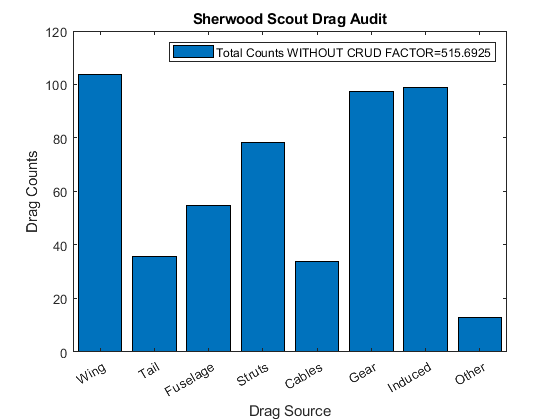

X=categorical({'Wing', 'Tail', 'Fuselage', 'Struts', 'Cables', 'Gear','Induced','Other'});
X=reordercats(X,{'Wing', 'Tail', 'Fuselage', 'Struts', 'Cables', 'Gear','Induced','Other'});

Y=[CD0_w_counts...
   CD0_tp_counts+CD0_tp_v_counts,...
   CD0_f_counts,...
   CD0_strut_counts+CD0_tail_strut_counts+CD0_jury_strut_counts,...
   CD0_tail_cable_counts,...
   CD0_gear_counts,...
   CDi_w_counts+CDi_tp_counts,...
   CD0_window_counts+CD0_antenna_counts];

bar(X,Y)
xlabel('Drag Source')
ylabel('Drag Counts')
title('Sherwood Scout Drag Audit')
legend(strcat('Total Counts WITHOUT CRUD FACTOR= ',num2str(CDtot_counts)))